# Prove that an adapted turbojet works better

# Quality data

clear all, close all, clc
%here there are all the efficiencies of the elements of the turbojet, with
%the compression ratio of the inlet and in the combustion chamber
e02 = 1;
pi12 = 1;
e23 = 1;
eq = 1;
piCC = 1;
e45 = 1;
nozzle = "conv";
epsi = 30;

# Project conditions

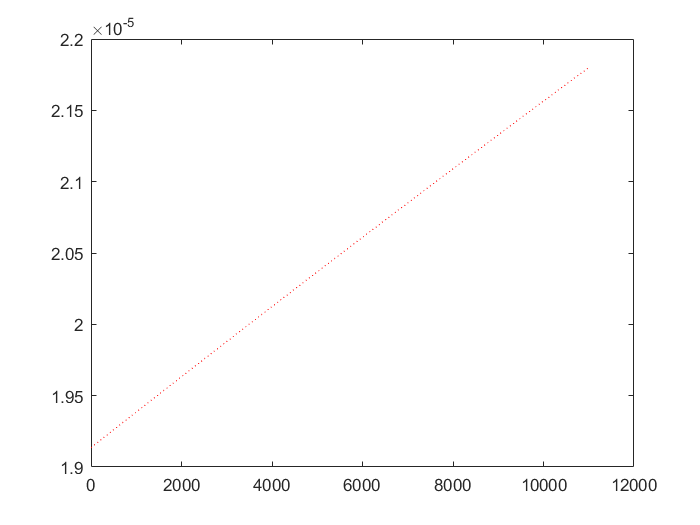


M0 = 0;
h = linspace(0,11000);
for i = 1:length(h)

    [P0(i), T0(i), rho0(i)] = ISA(h(i));
    g = 1.4;
    R = 287;
    m = 44;
    L = 42000000;
    Cp = R*g/(g-1);
    V0 = M0*sqrt(g*R*T0(i));
    T0t = T0(i)*(1 + (g-1)*(M0^2)/2);
    P0t = P0(i)*(1+ (g-1)*(M0^2)/2)^(g/(g-1));

    %% diffuser

    A0 = m/(V0*P0(i)/(R*T0(i)));
    if e02 ~= 1             %if e02 is not given, for M<1 the pressures are equal and for M>1 && M<5 the pressures are given by a relation from MIL-E-5007-D
        P2t = P0(i)*(1+ e02*(g-1)*(M0^2)/2)^(g/(g-1));
    elseif M0>1 && M0<5         %% only if supersonic
        P1t = P0t*(1-0.076*(M0-1)^1.35);
        P2t = P1t*pi12;
    else
        P1t = P0t;
        P2t = P1t*pi12;
    end
    T2t = T0t;      %supponiamo l'ingresso adiabatico
    M1 = 0.3;       %entry Mach
    P1 = P1t/((1+ (g-1)*(M1^2)/2)^(g/(g-1)));
    T1 = T0t/(1 + (g-1)*(M1^2)/2);
    V1 = M1*sqrt(g*R*T1);
    A1 = m/(V1*P1/(R*T1));

    %%compressor

    OPR = 22;
    P3t = P2t*OPR;
    T3t = T2t*(1 + (OPR^((g-1)/g) - 1)/e23);
    W = Cp*(T3t-T2t);

    %%combustion chamber

    T4t = 1400;
    f = Cp*(T4t-T3t)/(eq*L);
    c = f*m;
    P4t = P3t*piCC;

    %%turbine

    T5t = T4t-W/Cp;
    P5t = P4t*(1- (1-T5t/T4t)/e45)^(g/(g-1));

    %%nozzle

    if nozzle == "conv"
        adapted(i) = false;
        if P5t/P0(i) <= ((g+1)/2)^(g/(g-1))
            adapted(i) = true;
            Ps = P0(i);
        end
        if adapted(i)
            Ts = T5t*(P0(i)/P5t)^((g-1)/g);
            Ms = sqrt((2/(g-1))*((P5t/P0(i))^((g-1)/g)-1));
            Vs = Ms*sqrt(g*R*Ts);
        else
            Ps = P5t/((g+1)/2)^(g/(g-1));
            Ts = T5t*2/(g+1);
            Vs = sqrt(g*R*Ts);
        end
        As = m/(Vs*Ps/(R*Ts));
    elseif nozzle == "condiv"
        adapted(i) = false; %tratto l'ugello sempre come non adattato, al massimo al calcolo della spinta si elimineranno le due pressioni
        %%per ugello non adattato è necessaria la risoluzione di una
        %%equazione non lineare
        G = sqrt(g)*(2/(g+1))^((g+1)/(2*(g-1)));
        maxeval = 50;
        NPR = 0;
        for j=1:maxeval
            oldNPR = NPR;
            NPR = (G/(epsi*sqrt((2*g/(g-1))*(1-NPR^((g-1)/g)))))^g;
            if (NPR-oldNPR)*100/NPR < 0.1
                j = maxeval;
            end
        end
        Ps = NPR*P5t;
        Ts = T5t*NPR^((g-1)/g);
        Ms = sqrt((2/(g-1))*(T5t/Ts -1));
        Vs = Ms*sqrt(g*R*Ts);
        As = m/(Vs*Ps/(R*Ts));
    end

    %%performance

    if adapted(i)
        I_sp = (1+f)*Vs -V0;
        TSFC(i) = f/((1+f)*Vs - V0);
        E(i) = m*I_sp;
    else
        I_sp = (1+f)*Vs - V0 + As*(Ps-P0(i))/m;
        TSFC(i) = f/((1+f)*Vs - V0 + As*(Ps-P0(i))/m);
        E(i) = m*I_sp;
    end
end

figure(1)
plot(h, TSFC, "LineStyle",":", "Color",'r')

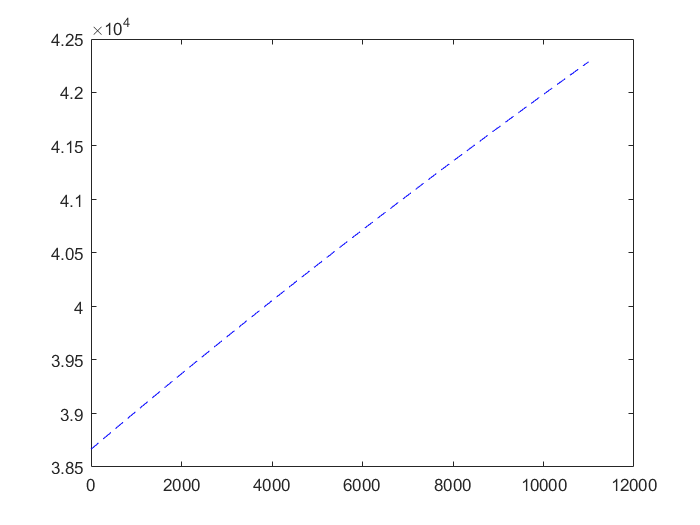


figure(2)
plot(h, E, "LineStyle","--", "Color",'b')

for i = 1:length(h)
    if adapted(i) == true
        figure(1)
        hold on
        plot(h(i), TSFC(i), "Marker","*")
        figure(2)
        hold on
        plot(h(i), E(i), "Marker","diamond")
    end
end

nnz(adapted)

ans = 0